# Homework Schumann - 28/10/2021

## Data

transcript_abundance = readtable('transcript_abundance.txt'); %genotypen (x), gene (Y)


%numeric (double matrix) from numeric data
numbers_only = transcript_abundance(:,2:end); 
data_num_m = table2array(numbers_only);

## Data Transformation

%log transformation
Log_data_abundance = log10(data_num_m);

## Histogram

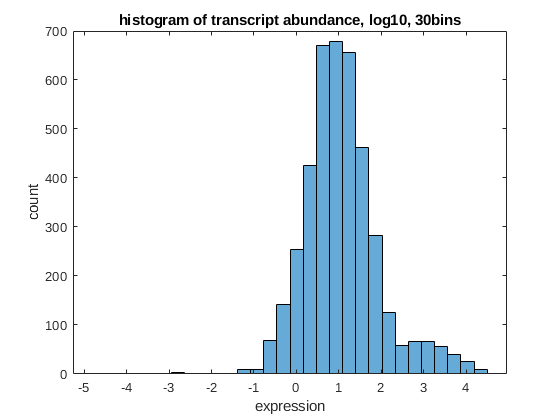

%create histogram

f1 = figure; 
figure(f1); 

histogram(Log_data_abundance,30)

title('histogram of transcript abundance, log10, 30bins')
xlabel('expression'); 
ylabel('count');

## calc. mean reps

%define num of reps manually 
num_reps = 3;

% preallocating the matrix 
[r,c] = size(data_num_m);
%calc needed num. of cols. after mean calc.
num_cols_mean_matrix = c./num_reps;
%create zero matrix of new size
mean_matrix = zeros(r, num_cols_mean_matrix);

j = 1;
for count = 1:num_cols_mean_matrix %loop in this case 4 times
    
    reps = (data_num_m(:,j:j+2)); %take three successive rows
    mean_matrix(:,count) = mean(reps,2); %calc mean of cols. per row
    
    j = j+3;
end

## normalize average matrix

% sum of all values in col
col_sum = sum(mean_matrix, 1);

% take each value of mean matrix & devide by col_sum
mean_matrix_norm = mean_matrix./col_sum;

% get the genotype names from the rawdata table
ColNamesOld = transcript_abundance.Properties.VariableNames;
ColNamesOld = ColNamesOld(2:end); %cut the first colums name

ColNamesNew = [];
%go through the old variable names, check for replicates, extract only the
%genotyp name and append to new array
for i = 1:length(ColNamesOld(1:end))
    Rep_name = ColNamesOld{i};
    GenT_name = extractBefore(Rep_name,"_"); %cut replicate ident. 
    if isempty(ColNamesNew) 
       ColNamesNew = cat(2, ColNamesNew, {GenT_name}); 
    elseif ~contains(ColNamesNew,GenT_name) 
       ColNamesNew = cat(2, ColNamesNew, {GenT_name}); %only write name if not already in array
    end
end

## transform to table

table_avg_norm = array2table(...
   mean_matrix_norm, ...
   'RowNames', transcript_abundance.Var1, ...
   'VariableNames', ColNamesNew);

## save output

%save table
writetable(table_avg_norm)
%save figure
saveas(f1,'Histogram_expressionlog10_b30.png')